# Code Project Fourier and Alexander Munoz

Put your name above

## Exercise

f = @(x) x*cos(16*x.^2);
exact_solution = 0.2

exact_solution = 0.2000

%  TODO: comment what a, b, alpha and N are
%there is no alpha
% a is the lower bound of the integral: -PI. b is the upper bound: 0. N is the amount of iterations in the function integration: 2.
a = -pi;%bug: using proper pi instead of an estimation
b = 0;
N = 2; 
%calls the function into name computed_integral
computed_integral = Composite_Simpsons_rule(f,a,b,N)

computed_integral = 0

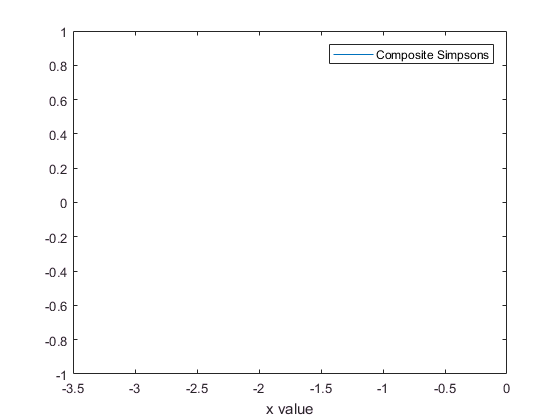

%sets the size of the scale to 0.01 from -pi to 0
x = [-pi:0.01:0];%bug: the percentage error was not 10^-8
plot(x,computed_integral)%bug: was not plotting the actual Simpson's Rule 
xlabel('x value')
legend('Composite Simpsons')

Function 

function I = Composite_Simpsons_rule(f,a,b,N)%bug: Improper function name
   %Solve for the zero values for the function given
    x = zeros(N+1, 1);
    
    %Will solve for the step size of the integration
    h = (b-a)/(N);
    %begins iterating from 1 to step N+1
    for i = 1:N+1
        x(i) = a + (i-1) *h;
    end
    
    %Initialize the Simpson's Rule to 0
    I = 0;
    for i = 1:N/2 - 1 %bug: upper bound was incorrect
        j = 2*i -1;
        I = I + h/3 * ( f(x(j)) + 4*f(x(j+1)) + f(x(j+2)) );%bug: subtraction when function is a summation and missing error
    end
end